Lab 5

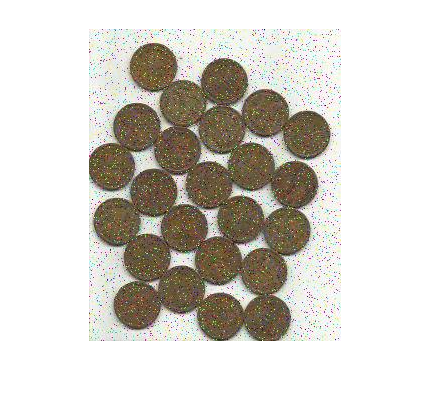

Image = LoadImage('corrupted_coins.jpg');

HistoGram

ImageHistogram(Image);

Mean Filter

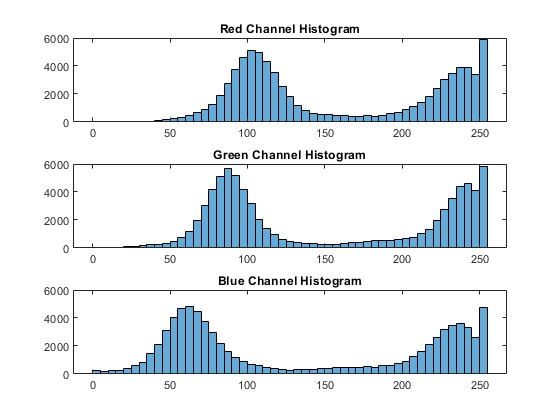

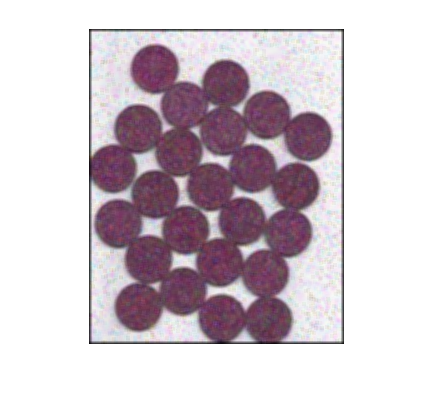

FilteredImage = MeanFilter(4, Image);
figure
imshow(FilteredImage);

Grayscale Image and histogram

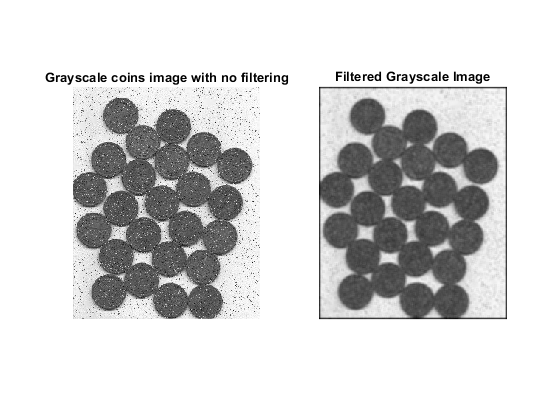

GrayImage = rgb2gray(Image); %% returns uint8 which is perfect for images
GrayFilteredImage = rgb2gray(FilteredImage);
figure
subplot(1,2,1);
imshow(GrayImage);
title("Grayscale coins image with no filtering");
subplot(1,2,2);
imshow(GrayFilteredImage);
title("Filtered Grayscale Image");

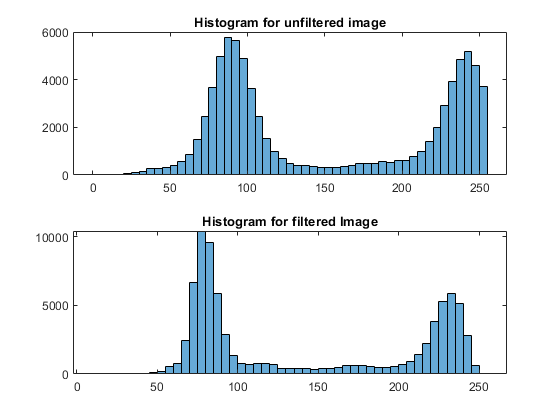

% Histogram
figure
subplot(2,1,1);
histogram(GrayImage);
title("Histogram for unfiltered image");
subplot(2,1,2);
histogram(GrayFilteredImage);
title("Histogram for filtered Image");

Thresholding

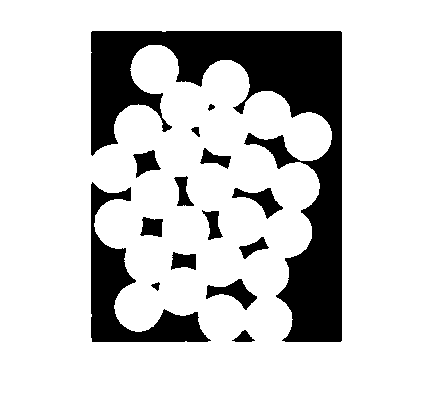

figure
imshow(imcomplement(imbinarize(GrayFilteredImage)));

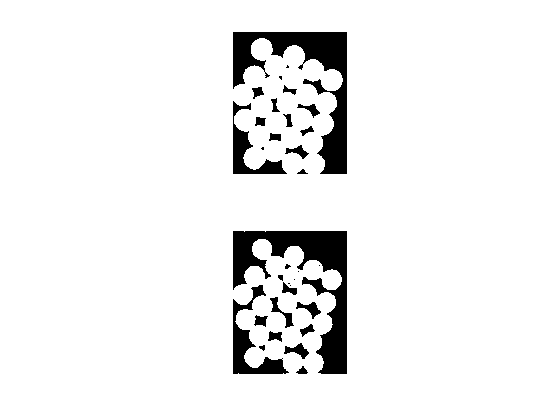

greyThreshImage = graythresh(GrayFilteredImage);
thresh = imcomplement(imbinarize(GrayFilteredImage, greyThreshImage));
manualThresh = imcomplement(imbinarize(GrayFilteredImage, 0.4));
figure
subplot(2,1,1);
imshow(thresh);
subplot(2,1,2);
imshow(manualThresh);

Structure element

circle = [0,1,1,1,1,1,1,0,
          1,1,1,1,1,1,1,1,
          1,1,1,1,1,1,1,1,
          1,1,1,1,1,1,1,1,
          1,1,1,1,1,1,1,1,
          1,1,1,1,1,1,1,1,
          1,1,1,1,1,1,1,1,
          0,1,1,1,1,1,1,0];
smallCircle = [0,0,1,1,1,0,0,
               0,1,1,1,1,1,0,
               1,1,1,1,1,1,1,
               1,1,1,1,1,1,1,
               1,1,1,1,1,1,1,
               0,1,1,1,1,1,0
               0,0,1,1,1,0,0];
           
           
cross = [0,1,0,
         1,1,1
         0,1,0];
box = [1,1,1,
       1,1,1,
       1,1,1]

box =      1     1     1
     1     1     1
     1     1     1


Erosion




figure
subplot(2,2,1);
crossErode = imerode(thresh,cross);
imshow(crossErode);
title("Erode 1 Cross");
subplot(2,2,2);
holder1 = imerode(thresh, circle)

holder1 = 315×255 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

circleErode = holder1

circleErode = 315×255 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

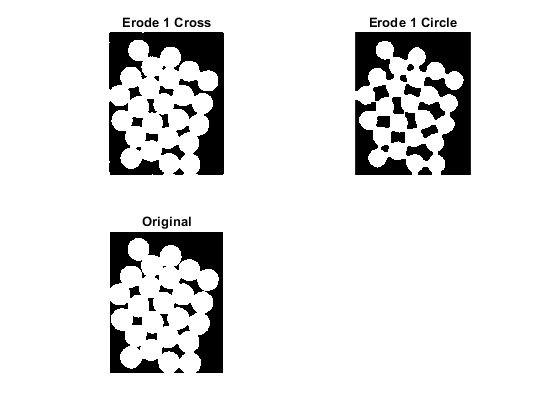

imshow(circleErode);
title("Erode 1 Circle");
subplot(2,2,3);
imshow(thresh);
title("Original");



%Erosion 2
circleErode = imerode(circleErode, circle);
holder2 = circleErode

holder2 = 315×255 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

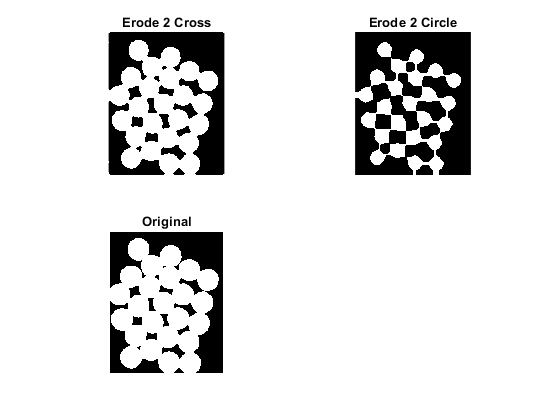

crossErode = imerode(crossErode, cross);
figure
subplot(2,2,1);
imshow(crossErode);
title("Erode 2 Cross");
subplot(2,2,2);
imshow(circleErode);
title("Erode 2 Circle");
subplot(2,2,3);
imshow(thresh);
title("Original");


circleErode = imerode(circleErode,circle);
holder3 = circleErode

holder3 = 315×255 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

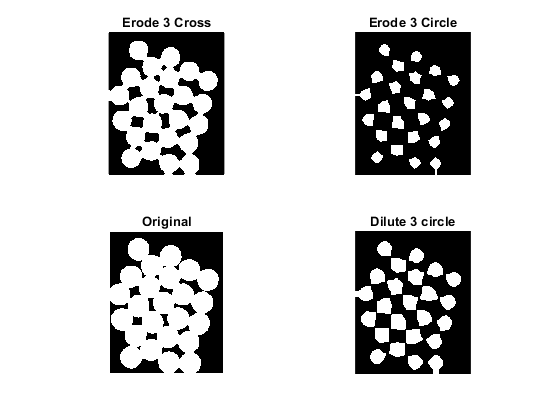

crossErode = imerode(crossErode, cross);
figure
subplot(2,2,1);
imshow(crossErode);
title("Erode 3 Cross");
subplot(2,2,2);
imshow(circleErode);
title("Erode 3 Circle");
subplot(2,2,3);
imshow(thresh);
title("Original");
subplot(2,2,4);
circleErode = imdilate(circleErode, circle);
imshow(circleErode);
holder4 = circleErode;
title("Dilute 3 circle");

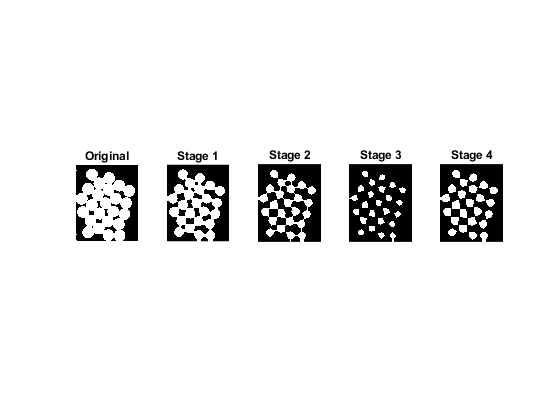


figure
subplot(1,5,1);
imshow(thresh);
title("Original");
subplot(1,5,2);
imshow(holder1);
title("Stage 1");
subplot(1,5,3);
imshow(holder2);
title("Stage 2");
subplot(1,5,4);
imshow(holder3);
title("Stage 3");
subplot(1,5,5);
imshow(holder4);
title("Stage 4");

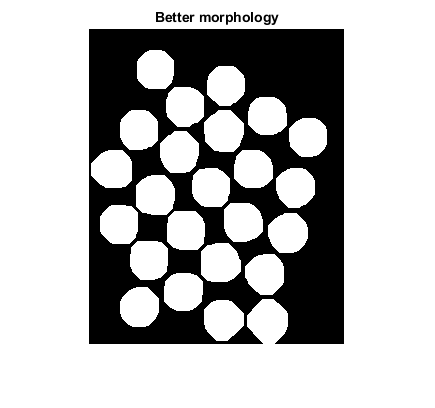

smallDisk = strel('disk', 8,4);
smalloct = strel('octagon', 9);
smalloct2 = strel('disk', 3,4);
smalldisk = strel('square', 2);

figure
subplot(1,1,1);
test = imerode(thresh, smalloct);
test = imerode(test, smallDisk);
test = imdilate(test, smalloct);
test = imclose(test, smallDisk);
test = imerode(thresh, smalloct);
test = imerode(test, smallDisk);
test = imdilate(test, smalloct);
test = imopen(test, smallDisk);
test = imdilate(test, smalloct2);
test = imdilate(test, smalldisk);
test = imfill(test, 'holes');
imshow(test);
title("Better morphology");

cc = bwconncomp(test);
disp("there are " + cc.NumObjects + " coins in the image");

there are 24 coins in the image


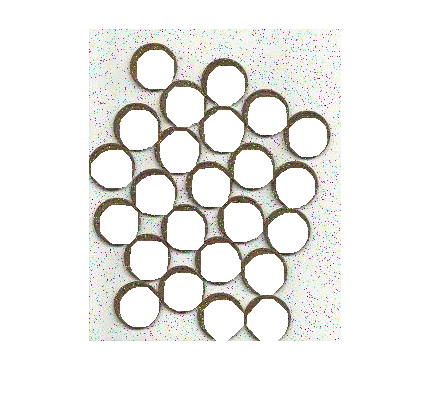

figure
white = cat(3, ones(size(GrayFilteredImage)), ones(size(GrayFilteredImage)), ones(size(GrayFilteredImage)));
imshow(Image);
hold on
h = imshow(white);
set(h, 'AlphaData', test)
hold off

Lab 6

stats = regionprops(test);
id = fopen('./log.txt');
fprintf(id,'ID Centroid-x Centroid-y Area Bbox1 Bbox2 Bbox3 Bbox4');
for i=1:size(stats)
    
    fprintf(id,'%i %0.1f %0.1f %i %0.1f %0.1f %0.1f %0.1f\n',stats.Area, stats.BoundingBox, stats.Centroid);
   
end
 fclose(id);


Bounding Boxes

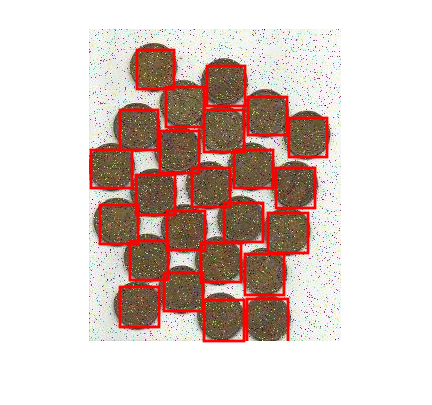

%% take this and put it in a function, easy
 figure
imshow(Image);
hold on
 for k = 1 : length(stats)
  thisBB = stats(k).BoundingBox;
  rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','r','LineWidth', 2);
 end
hold off

Smallest and Biggest

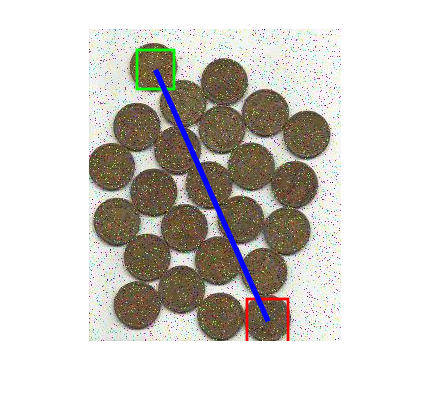

[smallestIndex, LargestIndex] = FindSmallestAndLargestRegion(stats);
figure
imshow(Image);
hold on
 thisBB = stats(LargestIndex).BoundingBox;
 
 largeCentre = [thisBB(1) + (thisBB(3)/2), thisBB(2) + (thisBB(4)/2)];
 rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','r','LineWidth', 2);
 thisBB = stats(smallestIndex).BoundingBox;
 rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','g','LineWidth', 2);
 % 1 is the left, 2 is the top, 3 is the width, 4 is the height

 line([stats(smallestIndex).Centroid(1), stats(LargestIndex).Centroid(1)],[stats(smallestIndex).Centroid(2), stats(LargestIndex).Centroid(2)], 'Color', 'b', 'LineWidth', 4);
hold off;